# Calculos Campo

% Campo magnetico
r =6% radio del tubo en el que esta el juego 

r = 6

I =40000% corriente

I = 40000

h =50% altura

h = 50

%N =5% num. espriras
g = 9.81; % gravedad
M0 = 4*pi*(10^-7); % permeabilidad del aire (miu)
masa = (130 + 50 )*40 % Kg

masa = 7200

tmax = sqrt((2*h)/g);
paso = 0.1; %  paso 
t=0:paso:tmax; % rango en el tiempo
% yi = 0; %ayuda
%vel = t.*g;% velocidad por segundo
vel = @(t) t.*g

vel = function_handle with value:
    @(t)t.*g



% Calculo Campo
%[z,B]=Calculo_campo(paso,t,h,g,M0,I,r) % llamada de la funcion
z = @(t) h + vel(0) .* t + (0.5.*-g.*t.^2);% Posicion en z
%z = @(t) (g*t.^2)/2;% Posicion en z
B = @(z) (M0*I*r.^2)./(2*(r.^2+z.^2).^(3/2)); %Campo

%z = @(t) (t.*g).*t+(1/2).*g.*t.^2;

z1 = z(t)

z1 =    50.0000   49.9509   49.8038   49.5585   49.2152   48.7737   48.2342   47.5966   46.8608   46.0269   45.0950   44.0649   42.9368   41.7105   40.3862   38.9637   37.4432   35.8246   34.1078   32.2930   30.3800   28.3689   26.2598   24.0526   21.7472   19.3438   16.8422   14.2425   11.5448    8.7490    5.8550    2.8629


b1 = B(z1)

b1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0004    0.0008    0.0015    0.0031


V = vel(t)

V =          0    0.9810    1.9620    2.9430    3.9240    4.9050    5.8860    6.8670    7.8480    8.8290    9.8100   10.7910   11.7720   12.7530   13.7340   14.7150   15.6960   16.6770   17.6580   18.6390   19.6200   20.6010   21.5820   22.5630   23.5440   24.5250   25.5060   26.4870   27.4680   28.4490   29.4300   30.4110


A = 2.*pi.*r

A = 37.6991


fem = @(t) vel(t).*B(z1).*h

fem = function_handle with value:
    @(t)vel(t).*B(z1).*A


FEM = fem(t)

FEM =          0    0.0003    0.0005    0.0008    0.0011    0.0014    0.0017    0.0021    0.0025    0.0030    0.0036    0.0042    0.0049    0.0058    0.0069    0.0082    0.0098    0.0119    0.0145    0.0179    0.0225    0.0288    0.0377    0.0505    0.0699    0.1007    0.1522    0.2447    0.4254    0.8127    1.7038    3.5304


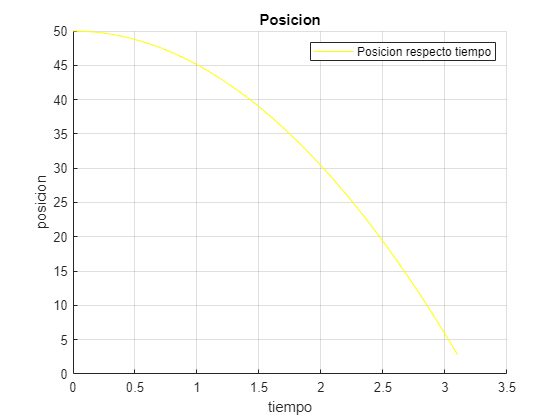

%torque magnetico
%torque = mdm*b1*sin(90);

%Magnetic dipole moment
mdm = I*A;   mdm = I*A^2*pi 

%motional emf
%e = -b1*V*h;

%flujo magnetico

%mflux = b1*A*cos(90);

%ley de Faraday
%ELF = mflux/t;
%ley de Lenz 
%LL = -LF;



% Grafica la Posicion respecto al tiempo 
clf;
hold on
plot(t,z1,'y')
title("Posicion")
legend("Posicion respecto tiempo")
xlabel("tiempo")
ylabel("posicion")
grid on
hold off

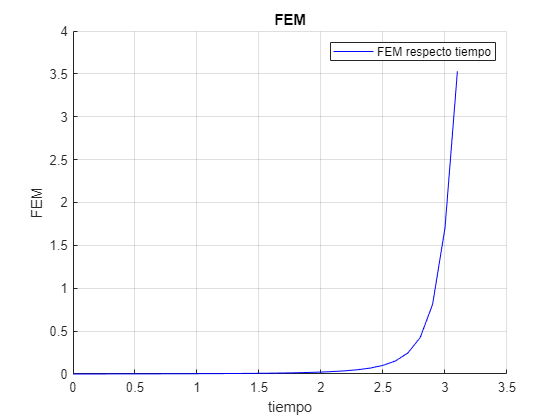


% Grafica fem respecto al tiempo
clf;
hold on
plot(t,FEM,'b')
title("FEM")
legend("FEM respecto tiempo")
xlabel("tiempo")
ylabel("FEM")
grid on
hold off

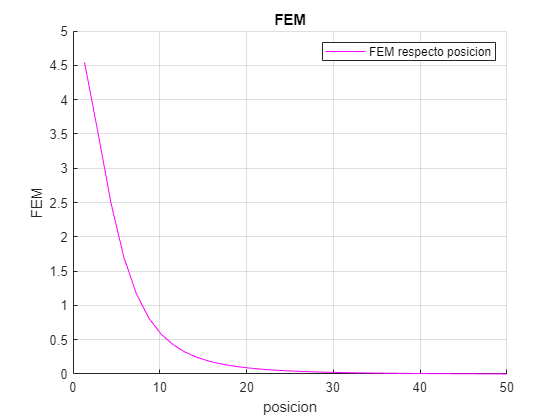


% Grafica fem respecto a la posicion
clf;
hold on
plot(z1,FEM,'m')
title("FEM")
legend("FEM respecto posicion")
xlabel("posicion")
ylabel("FEM")
grid on
hold off

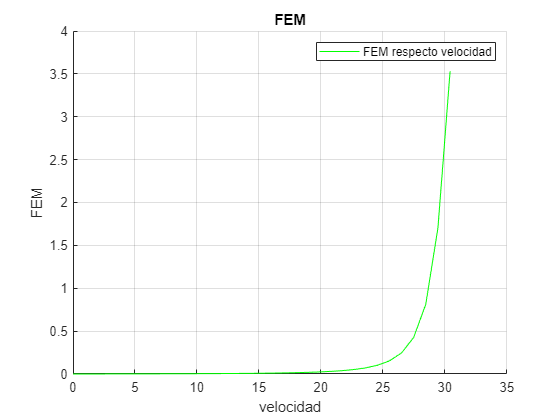


% Grafica la fem respecto a la Velocidad 
clf;
hold on
plot(V,FEM,'g')
title("FEM")
legend("FEM respecto velocidad")
xlabel("velocidad")
ylabel("FEM")
grid on
hold off


%mdm = I*A^2*pi 
% Flujo del campo magnetico
% A = pi*r^2; %Superficie
% vel = % velocidad por segundo
% fi = (M0.*N.*I./z).*A; %Flujo magnetico
% fi = B.*A %Flujo 
% Integrar 
% plot(z,fi,'*b');
% plot(t,fi,'-m-);
% grid on

% (Fg - Fz) / m         (Fg(masa*gravedad) - Fz(%B.*A -> Flujo(fi))) / m
% a = (Fz + Fg) / m % aceleracion
% I =   %Corriente 
% L = %Corriente Inducida 
% F = m * a % masa por aceleracion 
% Fuerza necesaria para frenarlo

% disp("Fuerza Neta")
%F = masa * g   Fmg

F = 70632

% F = I * 2 * 
% fem instantanea, B*A (sin velocidad por que es el punto 0; instantanea)

%----------------------------------------------------------------------------------
%Fuerza 
Fmg = m*g %masa*gravedad

%Momento magnetico
%%M = I.*A %corriente * Area
M = @(I) I.*A;

%Flujo magnetico
%%fmag = B.*A %es el simbolo del circulito con una raya en medio vertical)
fmag = @(b) b.^A;

%Voltaje (derivada del flujo)
%Voltaje = diff(fmag) %diferencial de flujo magnetico
Voltaje = @(fuerza) diff(fuerza);

%Corriente Inducida
%%IInducida = Voltaje/r %voltaje/radio
IInducida = @(volts) Voltaje/r;

%Fuerza del Campo  -------ESTO LO DEFINE EL IMAN EN CANVAS O INVENTAMOS UN VALOR REALISTA TAMAÑO
%%FB = (B.*M)./z %Campo*Permeabilidad del espacio / posicion en z cada segundo 
FB = @(B,M,z) (B.*M)./z;

%Aceleracion
%a = (FB - Fmg)./m %Fuerza del campo - Fuerza / masa
a = @(FB) (FB - Fmg)./m;

%Voltaje en el siguiente segundo

%Campo Inducido
%BInducido = M0*IInducida./2.*z %(Permeabilidad*Corriente Inducida/ 2 * posicion siguiente z segun el tiempo)
BInducido = @(M0) M0*IInducida./2.*z;

%Fuerza del campo

ETAPA 2

%Propiedades del medio
%mur = ;                     % Permeabilidad relativa del medio
mu0 = 4*pi*10^(-7);                     % Permeabilidad magnética en el vacío [N/A^2]
%mu = ;                      % Permeabilidad del medio
g = 9.81;                       % Constante de gravedad(m/s^2)

%Valores de la espira de la espira
%N=;                         % Cantidad de espiras (30)
Ohm = 1.71*10^(-8) ;                     % Resistencia de la espira (0.05) //resistencia del cobre 
%R= ;                        % Radio de la espira (m) (0.01)
%
% Propiedades del dipolo
%M = ;                             % Momento magnético dipolar (Am^2) 30
m = 5;                           % Masa del dipolo magnético (kg) 0.003



